# Solid body representation in 3D

Tools to plot objects in 3D.

We have several tools to draw an object or a frame in 3D: VOXEL , PSOLIDO , PFRAME 

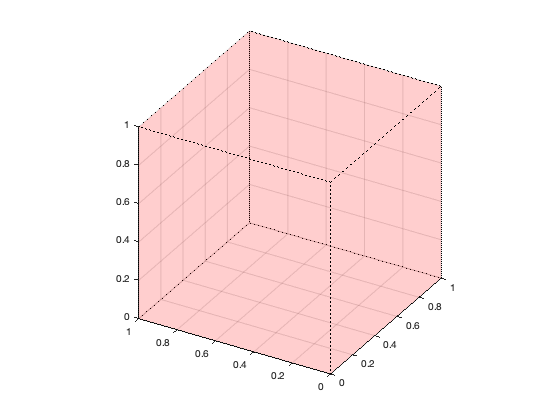

% VOXEL: Dibujamos un cubo de lado unidad, en color rojo, trasparente 0.1
a=1; b=1; c=1;
voxel([0 0 0],[a b c],'r',0.1);
grid on		% Se establece una rejilla
view(-60,30)	% Se establece el punto de vista
axis equal

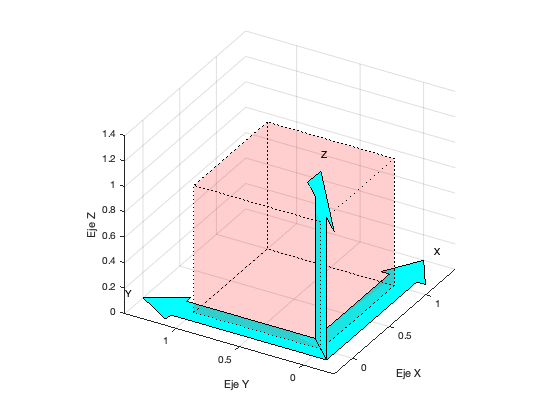

% PFRAME: dibujamos la trama T0 dada en coordenadas homogéneas
T0=eye(4);
pframe(T0,'c',1.4);
view(-60,30)

% PSOLIDO: un prisma definido por sus 8 vértices. 
P=psolido

P =          0    1.0000    1.0000    0.5500    0.5500    0.4500         0         0    0.4500    0.5500    1.0000         0    0.4500    0.4500    0.5500    1.0000
         0         0         0    1.5000    1.5000    1.5000         0         0    1.5000    1.5000         0         0    1.5000    1.5000    1.5000         0
         0         0    0.5000    0.5000         0         0         0    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000         0         0         0


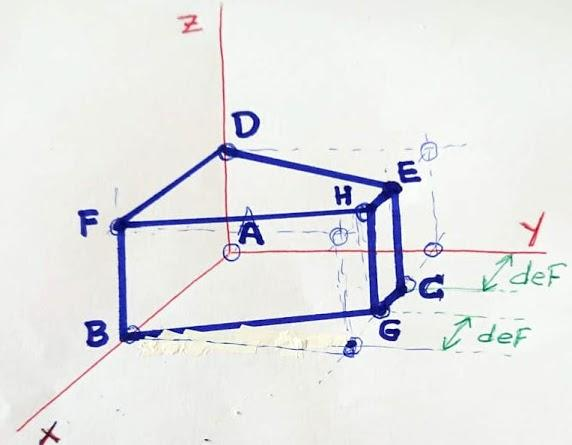

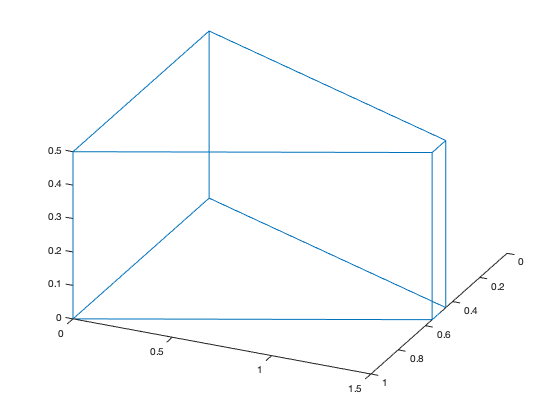


% La estructura de datos P es fácil de representar en 3D con plot3:
Pp=P'; plot3(Pp(:,1), Pp(:,2),Pp(:,3))
view([120 30])